read .wav file

resample (re sampling frequency)

generate signal: 

- type (rect, tone, tone-complex, noise)

- sampling frequency

- duration

- periodicity (rect)

- frequency/ies (tone, tone-complex)

plot: time signals

clear ylim

if input=="generate"
    if type_signal=="tone complex"
        fs=fs1
        t = 0:1/fs1:T
        fn = fs1 / 2;
    
        %generate a tone complex
        y= sin(2*pi*frequencies(1)*t)+ sin(2*pi*frequencies(2)*t)+sin(2*pi*frequencies(3)*t) +sin(2*pi*frequencies(4)*t);
        %play the sound
        %sound(generate_signal, fs);
    elseif type_signal=='noise'
        t = 0:1/fs1:T
        % Generate white noise
        y = randn(1, length(t));
    elseif type_signal=='rect'
        t = 0:1/fs1:T
        % Generate rectangular pulse signal
        y_rect = rectpuls(t1 - T/2, 2);
    elseif type_signal=="tone"
        t = 0:1/fs1:T
        % Generate the tone
        y = sin(2 * pi * frequencies(1) * t);
    end


elseif input=="wav"  
    [y, fs] = audioread([fname])

    y = resample(y, fs2, fs);
    fn = fs2 / 2;

    %make the signal 4 seconds
    %nb_samples = round(T * fs2);
    %y = y(1:nb_samples);
    t = (0:length(y)-1) / fs2;

    fs=fs2

    %play the sound
    %sound(y_signal, fs_y_signal);

end

fs = 20000

t =          0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0011    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024


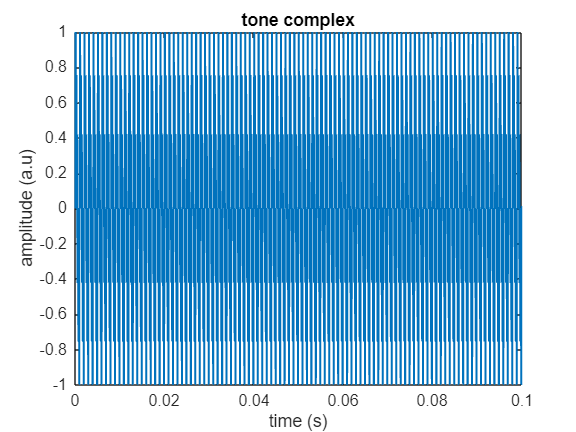


figure;
plot(t, y);
title(type_signal)
xlabel('time (s)');
ylabel('amplitude (a.u)')
xmin=0;
xmax=0.1;
xlim([xmin xmax]) 
ymin=-1;
ymax=1;
ylim([ymin ymax]) 


y_long=y

y_long =          0    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208
